% experimentPath = "../data/type1/46/";
experimentPath = "../data/type1/258/";
% experimentPath = "../../static/experiment/type1/355/";
Fs = 44100;
fBegin = 2000;
fEnd = 8000;
m2s1 = 0.00;
m2s2 = 0.00;
soundSpeed = 347;

正在处理../data/type1/258/A_to_Z.wav


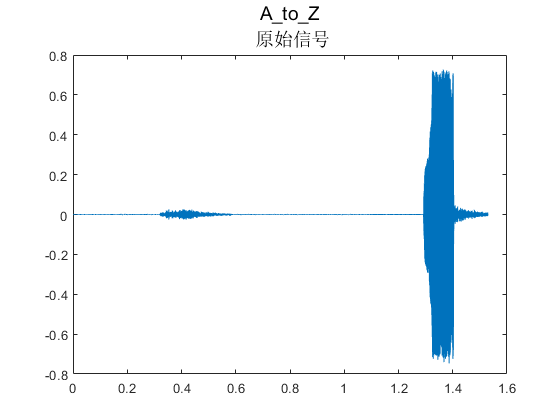

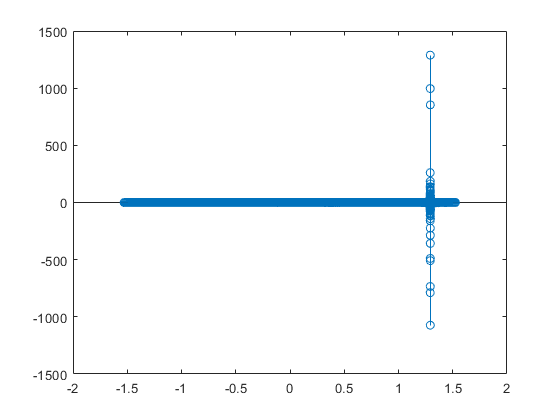

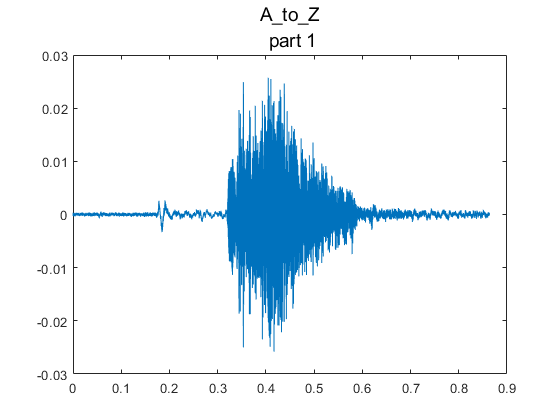

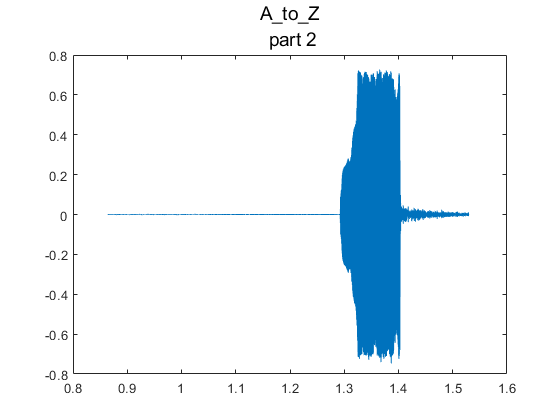

正在处理第一段


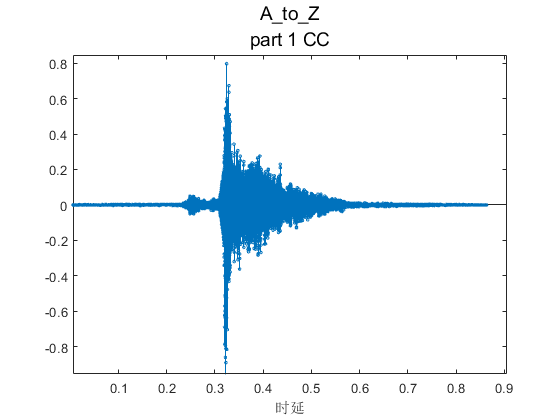

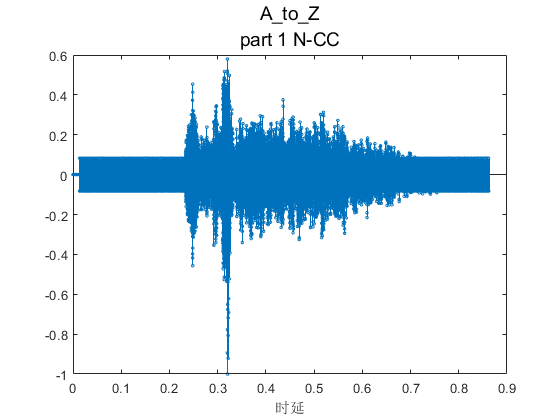

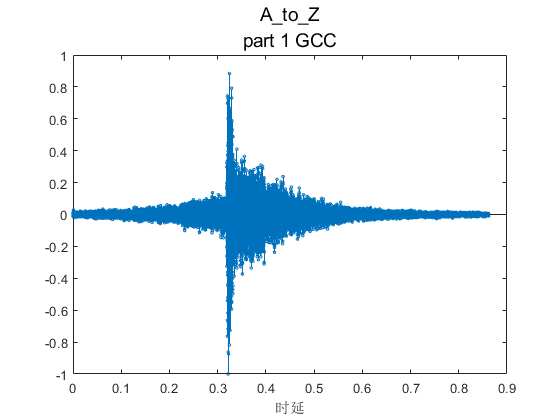

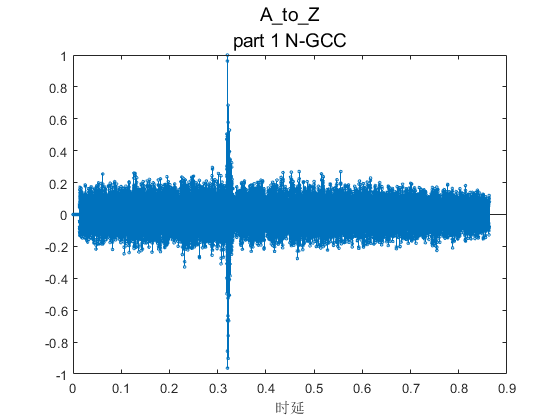

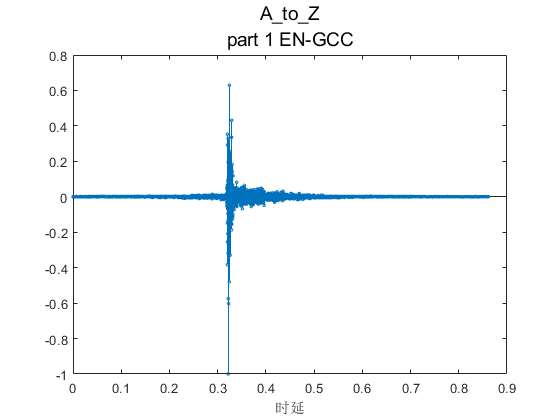

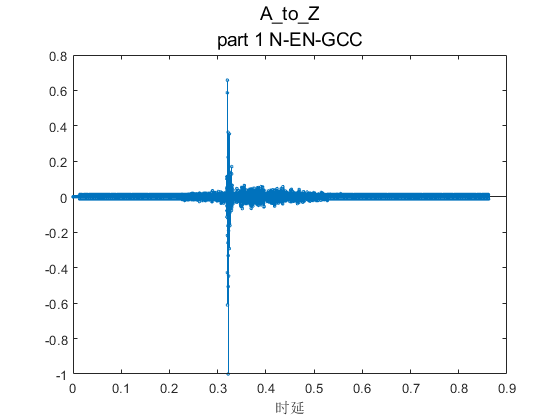

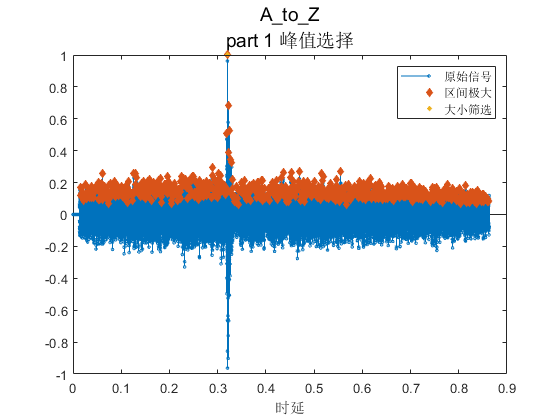

正在处理第二段


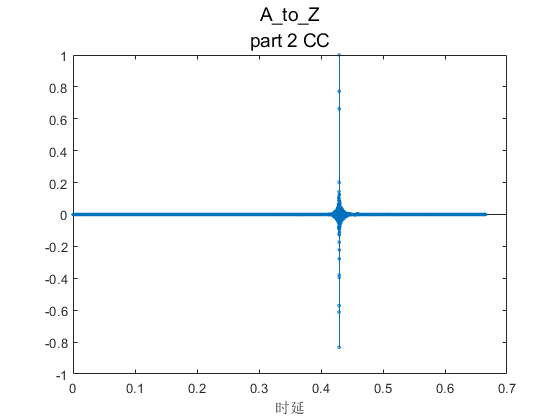

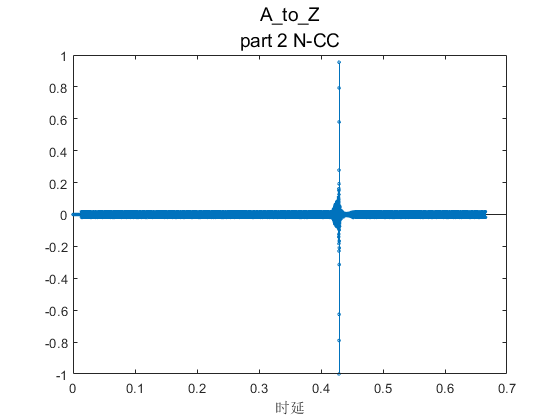

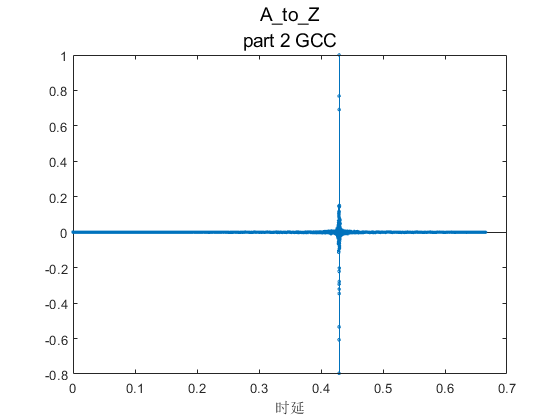

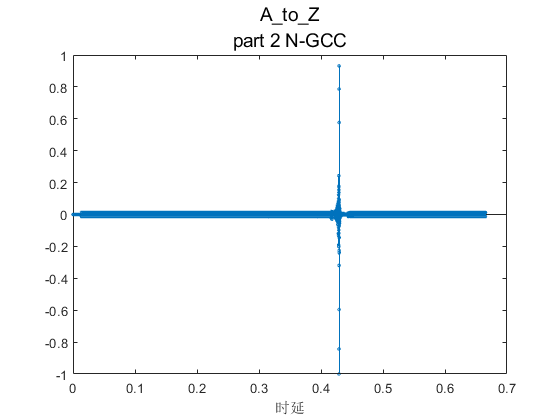

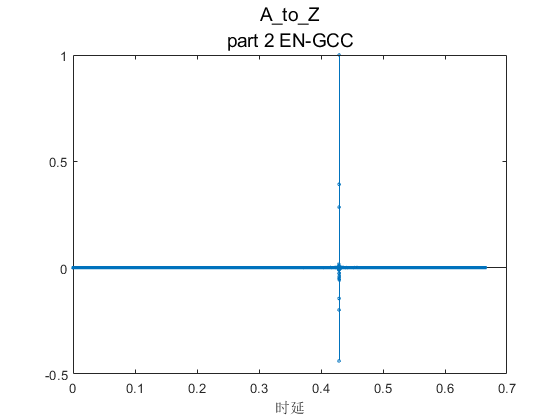

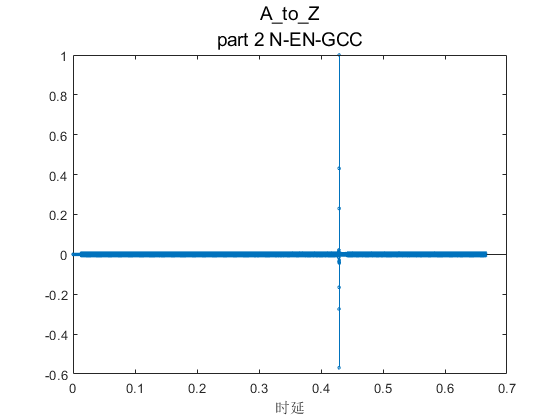

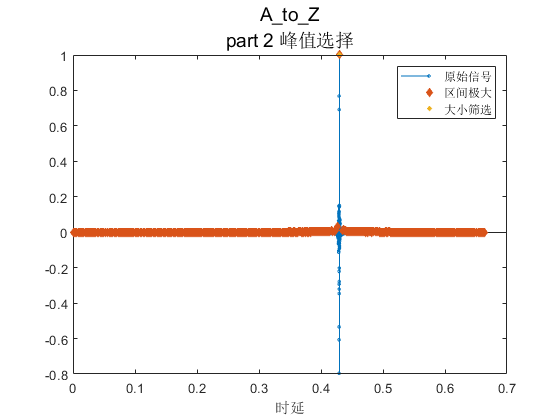

正在处理../data/type1/258/Z_to_A.wav


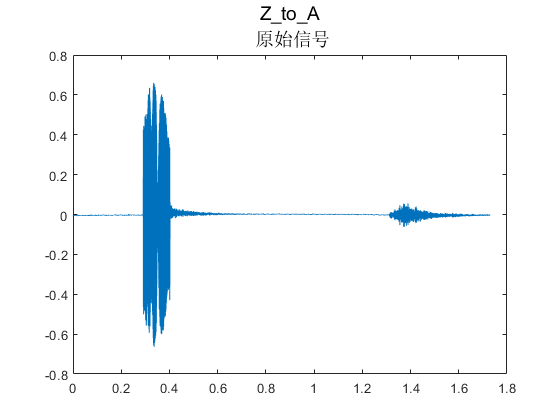

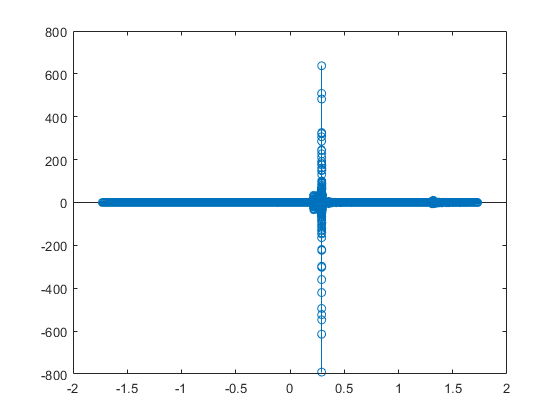

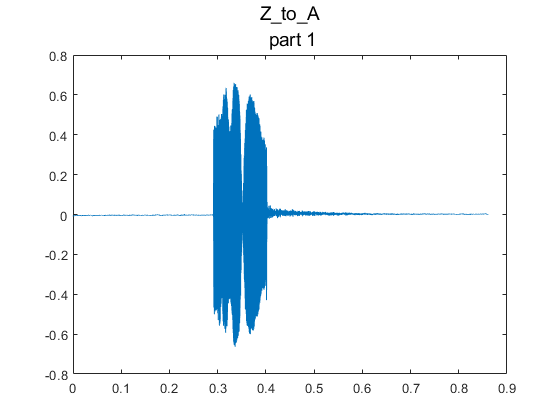

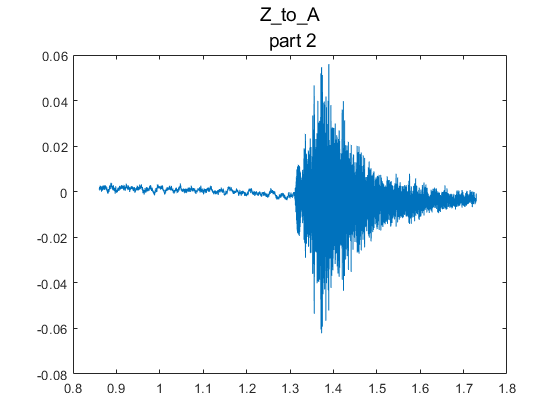

正在处理第一段


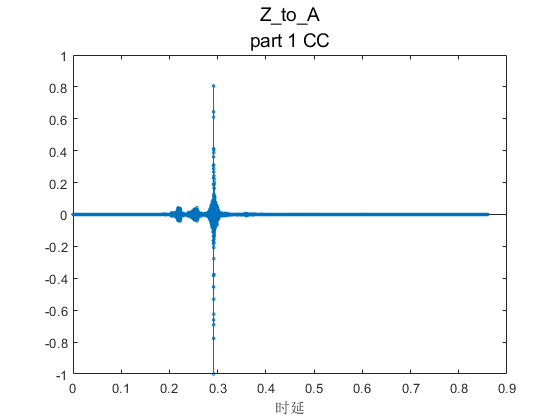

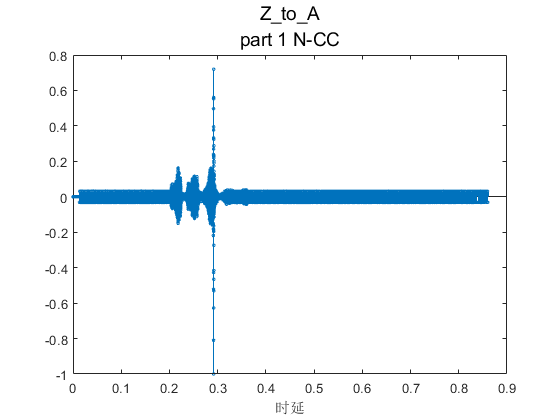

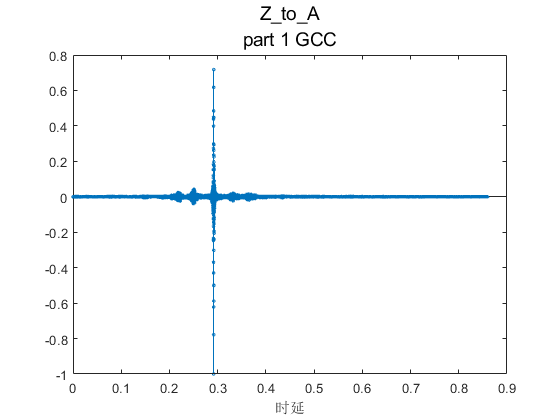

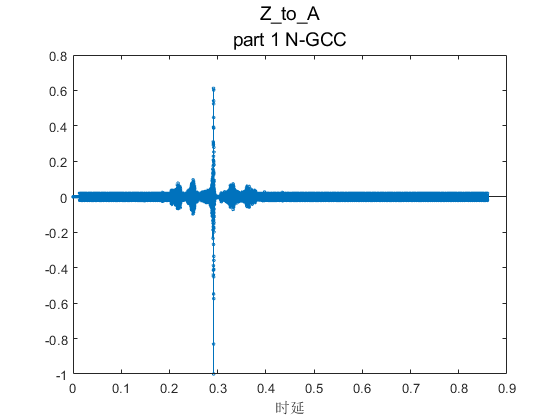

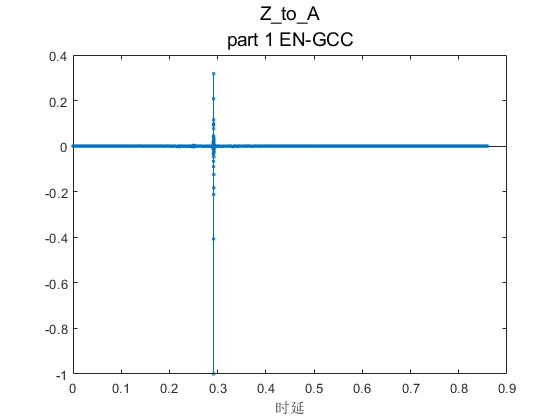

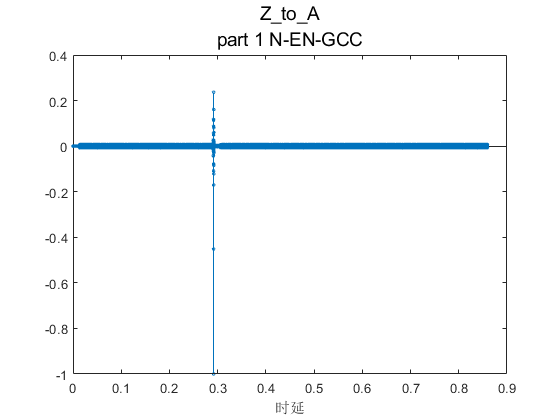

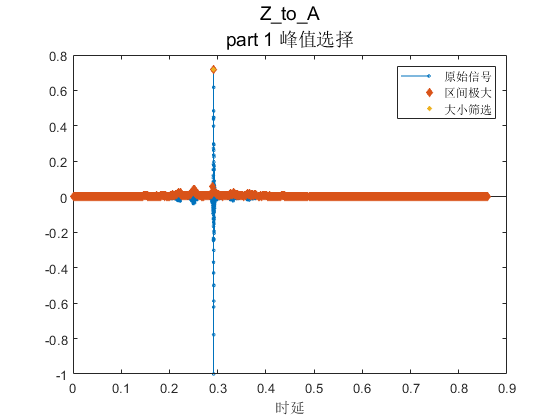

正在处理第二段


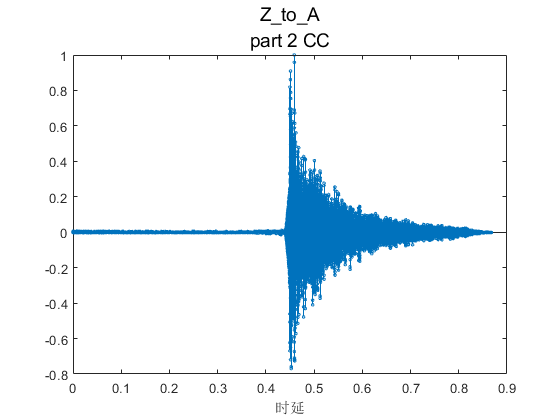

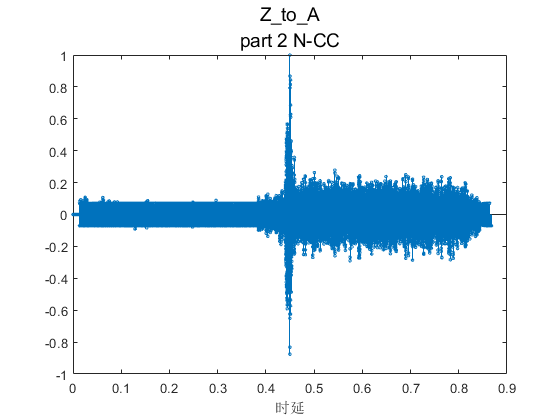

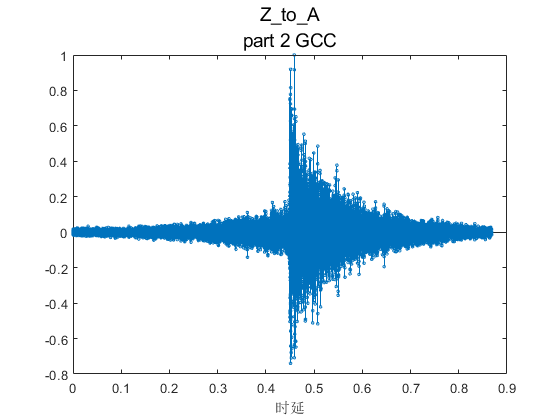

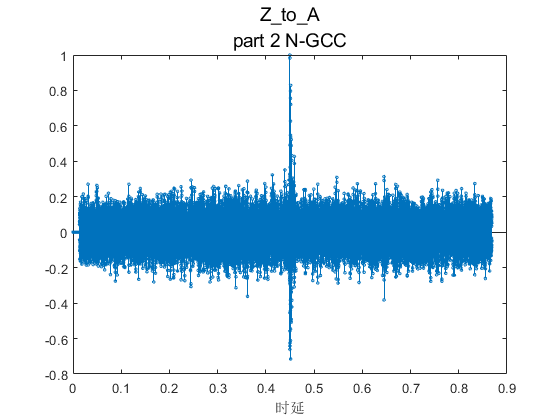

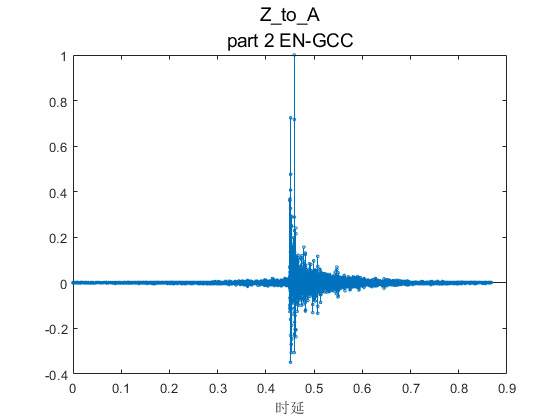

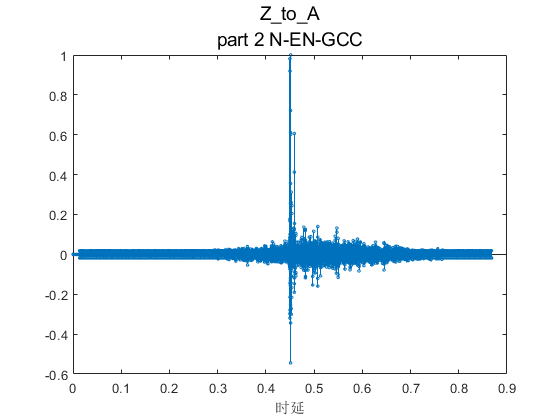

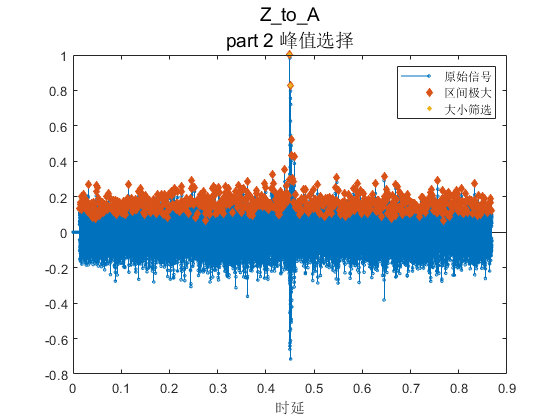

a = 7.9865

name = 30×1 string 数组
    "A_to_Z_fig1.png"
    "A_to_Z_fig2.png"
    "A_to_Z_fig3.png"
    "A_to_Z_fig4.png"
    "A_to_Z_fig5.png"
    "A_to_Z_fig6.png"
    "A_to_Z_fig7.png"
    "A_to_Z_fig8.png"
    "A_to_Z_fig9.png"
    "A_to_Z_fig10.png"
    "A_to_Z_fig11.png"
    "A_to_Z_fig12.png"
    "A_to_Z_fig13.png"
    "A_to_Z_fig14.png"
    "A_to_Z_fig15.png"
    "Z_to_A_fig1.png"
    "Z_to_A_fig2.png"
    "Z_to_A_fig3.png"
    "Z_to_A_fig4.png"
    "Z_to_A_fig5.png"
    "Z_to_A_fig6.png"
    "Z_to_A_fig7.png"
    "Z_to_A_fig8.png"
    "Z_to_A_fig9.png"
    "Z_to_A_fig10.png"
    "Z_to_A_fig11.png"
    "Z_to_A_fig12.png"
    "Z_to_A_fig13.png"
    "Z_to_A_fig14.png"
    "Z_to_A_fig15.png"


desc = 30×1 string 数组
    "A_to_Z origin"
    "A_to_Z part 1 CC"
    "A_to_Z part 1 N-CC"
    "A_to_Z part 1 GCC"
    "A_to_Z part 1 N-GCC"
    "A_to_Z part 1 EN-GCC"
    "A_to_Z part 1 N-EN-GCC"
    "A_to_Z part 1 selected peak"
    "A_to_Z part 2 CC"
    "A_to_Z part 2 N-CC"
    "A_to_Z part 2 GCC"
    "A_to_Z part 2 N-GCC"
    "A_to_Z part 2 EN-GCC"
    "A_to_Z part 2 N-EN-GCC"
    "A_to_Z part 2 selected peak"
    "Z_to_A origin"
    "Z_to_A part 1 CC"
    "Z_to_A part 1 N-CC"
    "Z_to_A part 1 GCC"
    "Z_to_A part 1 N-GCC"
    "Z_to_A part 1 EN-GCC"
    "Z_to_A part 1 N-EN-GCC"
    "Z_to_A part 1 selected peak"
    "Z_to_A part 2 CC"
    "Z_to_A part 2 N-CC"
    "Z_to_A part 2 GCC"
    "Z_to_A part 2 N-GCC"
    "Z_to_A part 2 EN-GCC"
    "Z_to_A part 2 N-EN-GCC"
    "Z_to_A part 2 selected peak"


tic
[a, name, desc] = calc_distance(experimentPath + "A_to_Z.wav", ...
    experimentPath + "Z_to_A.wav", ...
    experimentPath + "chirp.wav", ...
     m2s1, m2s2, Fs, fBegin, fEnd, soundSpeed)

toc

历时 11.260593 秒。


k = 1000

k = 1000

figure;
fp = @(x) (k .^ x - 1)/(k - 1);
fplot(fp, [0,1])
hold on;
fn = @(x) -(k .^ (-x) - 1) / (k - 1)

fn = 包含以下值的 function_handle :
    @(x)-(k.^(-x)-1)/(k-1)


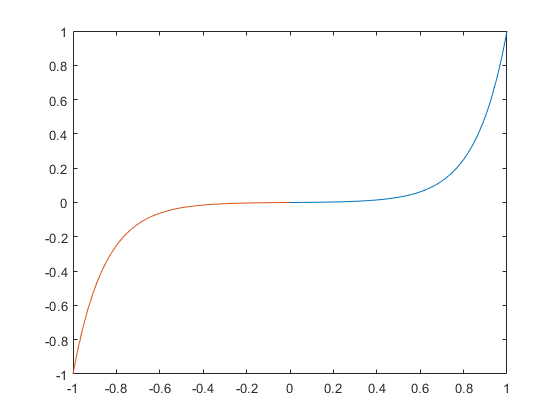

fplot(fn, [-1,0])